# PRÁCTICA INTEGRACIÓN NUMÉRICA

Aplicamos las fórmulas implementadas al cálculo de la integral de la siguiente función:

x=0:0.01:2*pi

x =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


f= cos(x.^2-1)

f =     0.5403    0.5404    0.5406    0.5411    0.5416    0.5424    0.5433    0.5444    0.5457    0.5471    0.5487    0.5504    0.5524    0.5544    0.5567    0.5591    0.5617    0.5644    0.5673    0.5703    0.5735    0.5769    0.5804    0.5840    0.5878    0.5918    0.5959    0.6002    0.6045    0.6091    0.6137    0.6186    0.6235    0.6286    0.6338    0.6391    0.6445    0.6501    0.6558    0.6616    0.6675    0.6735    0.6796    0.6858    0.6921    0.6985    0.7050    0.7115    0.7182    0.7249


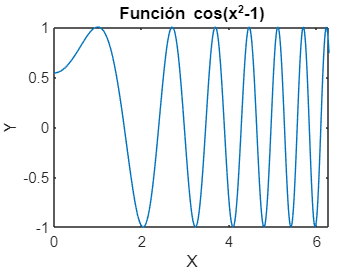

%Representación de la función en [0,2*pi] y del área bajo ella.
plot(x,f) 
hold on
title('Función cos(x^2-1)')
xlabel('X')
ylabel('Y')
hold off

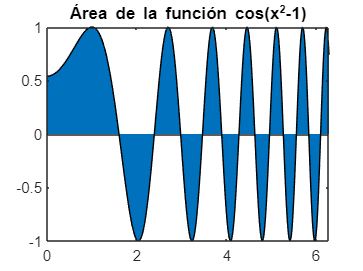

area(x,f)
title('Área de la función cos(x^2-1)')

%Definimos la función y los extremos de la integral
func = @(x) cos(x.^2-1)

func = function_handle with value:
    @(x)cos(x.^2-1)


a=0

a = 0

b=2*pi

b = 6.2832


%Aplicamos las diferentes fórmulas
%Fórmulas del rectángulo
[rectangulo_izquierda_Ix,rectangulo_izquierda_I]=rectangulo_izquierda(func,a,b)

Fórmula del rectángulo izquierda


I = 3.3948

Ix = 0.9211

El valor exacto es 0.921082
El valor aproximado es 3.394820


er = 2.6857

El error relativo cometido es: 2.685687

rectangulo_izquierda_Ix = 0.9211

rectangulo_izquierda_I = 3.3948

[rectangulo_derecha_Ix,rectangulo_derecha_I]=rectangulo_derecha(func,a,b)

Fórmula del rectángulo derecha


I = 4.4699

Ix = 0.9211

El valor exacto es 0.921082
El valor aproximado es 4.469868


er = 3.8528

El error relativo cometido es: 3.852846

rectangulo_derecha_Ix = 0.9211

rectangulo_derecha_I = 4.4699

[punto_medio_Ix,punto_medio_I]=punto_medio(func,a,b)

Fórmula del punto medio


I = -5.3395

Ix = 0.9211

El valor exacto es 0.921082
El valor aproximado es -5.339507


er = 6.7970

El error relativo cometido es: 6.796995

punto_medio_Ix = 0.9211

punto_medio_I = -5.3395

%Fórmula del trapecio
[trapecio_Ix,trapecio_I]=formula_trapecio(func,a,b)

Fórmula del trapecio
El valor aproximado mediante la formula del trapecio es: 3.932344
El valor aproximado mediante el comando trapz es: 0.918701
El valor exacto es: 0.921082
El error relativo cometido es: 3.280330

trapecio_Ix = 0.9211

trapecio_I = 3.9323

%Fórmula de Simpson 1/3
[simpson_Ix,simpson_I]=formula_Simpson(func,a,b)

Fórmula de Simpson 1/3
El valor exacto es 0.921082
El valor aproximado es -2.248890
El error relativo cometido es: 3.441575

simpson_Ix = 0.9211

simpson_I = -2.2489